# Herramientas Matemáticas  

### Ejercicio 1

Grafique el sistema {$M$} respecto de {$O$} para cada una de las siguientes matrices  de rotación:  

a. $\degree {\mathrm{Rot}}_M =\left\lbrack \begin{array}{cc}
0\ldotp 5 & -0\ldotp 866\\
0\ldotp 866 & 0\ldotp 5
\end{array}\right\rbrack$

Esta matriz de rotación es lo mismo que ${\textrm{Rot}}_Z \left(\frac{\pi }{3\;}\right)$.

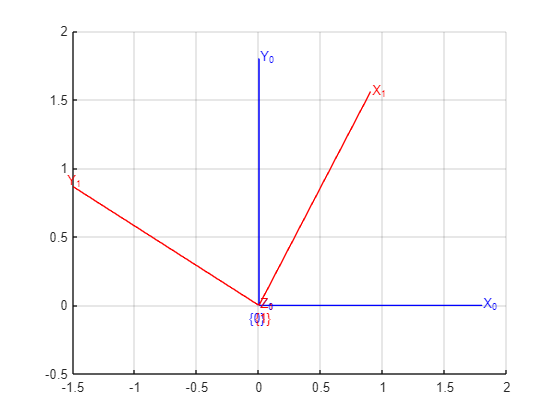

clear; close all;
T0 = eye(3);
T1 = [0.5 -0.866 0; 0.866 0.5 0; 0 0 1];

figure
hold on

xlim([0.000 1.000])
ylim([0.000 1.000])
trplot(T0,'color','b','frame','0','length',1.8)
trplot(T1,'color','r','frame','1','length',1.8)    

grid on
axis([-1.5 2 -.5 2 -2 2])
view(0,90)

b. ${\degree \textrm{Rot}}_M =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
-1 & 0 & 0\\
0 & -1 & 0
\end{array}\right\rbrack$

Esta matriz de rotación es lo mismo que ${\textrm{Rot}}_{Y_1 } \left(-\pi \right)\to {\textrm{Rot}}_{Z_1 } \left(-\pi \;\right)$.

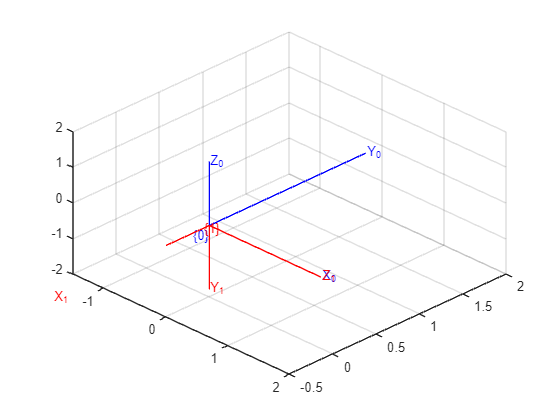

T2 = eye(4);
T3 = [0 0 1 0; -1 0 0 0; 0 -1 0 0; 0 0 0 1];

figure
hold on
trplot(T2,'color','b','frame','0','length',1.8)
trplot(T3,'color','r','frame','1','length',1.8)    
grid on
axis([-1.5 2 -.5 2 -2 2])
view(45,45)

c. $\degree {\textrm{Rot}}_M =\left\lbrack \begin{array}{ccc}
0\ldotp 50 & -0\ldotp 75 & -0\ldotp 433\\
0\ldotp 866 & 0\ldotp 433 & 0\ldotp 25\\
0 & -0\ldotp 5 & 0\ldotp 866
\end{array}\right\rbrack$

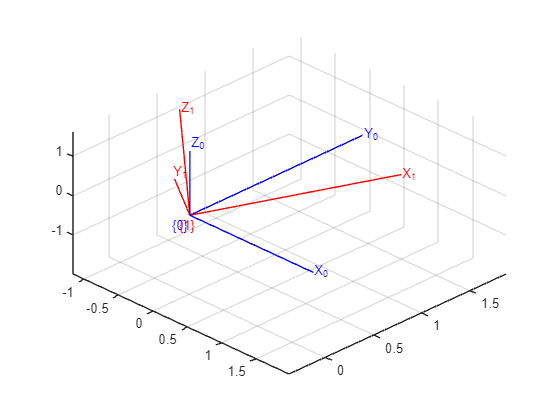

T4 = eye(4);
T5 = [0.5 -0.75 -0.433 0; 0.866 0.433 0.25 0; 0 -0.5 0.866 0; 0 0 0 1];

figure
hold on
trplot(T4,'color','b','frame','0','length',1.8)
trplot(T5,'color','r','frame','1','length',1.8)    
grid on
axis([-1.5 2 -.5 2 -2 2])
view(45,45)

Se recomienda usar el toolbox de “rtb” de Peter Corke para Matlab. 

### Ejercicio 2 (obligatorio)

Exprese cada uno de los siguientes vectores en el sistema de  referencia {$O$} sabiendo que sus coordenadas son respecto al sistema {$M$}, el cual sufrió la  rotación indicada. Realice un gráfico donde se aprecie el vector y sus coordenadas en ambos  sistemas.  

a. ${}^{M}a = $$\left\lbrack \begin{array}{cc}
1 & 0\ldotp 5
\end{array}\right\rbrack$; {$M$} rotó de -17° en $Z_O$


$${}^{O}a = $$


clear; close all;
T0 = eye(3);
T1 = rotz(-0.297);
am=[1; 0.5; 0];
a0=T1*am;
figure;
hold on;
trplot(T0,'color','b','frame','0','length',1.8)
trplot(T1,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [a0(1),a0(2),a0(3)])
grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(0,90)


b. ${}^{M}b
$$=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack$ {$M$} rotó de 35° en $Y_O$


$${}^{O}b
$$


clear; close all;
T2  =eye(3);
T3 = roty(0.61087);
bm=[0; 0; 1;];
b0=T3*bm

b0 =     0.5736
         0
    0.8191


figure 
hold on
trplot(T2,'color','b','frame','0','length',1.8)
trplot(T3,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [b0(1),b0(2),b0(3)])
grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(0,0)


c. ${}^{M}c$$=\left\lbrack \begin{array}{ccc}
1 & 0\ldotp 5 & 0\ldotp 3
\end{array}\right\rbrack$ {$M$} rotó de 90° en $Y_O$

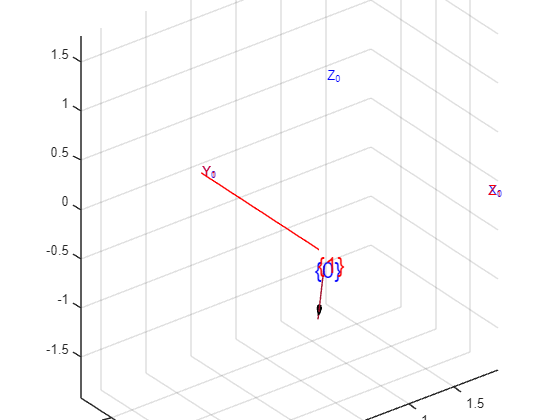

clear; close all;
T4 = eye(3);
T5 = roty(3.1416/2);
cm=[1; 0.5;0.3];
c0=T5*cm;
figure 
hold on
trplot(T4,'color','b','frame','0','length',1.8)
trplot(T5,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [c0(1),c0(2),c0(3)])
grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(3)

### Ejercicio 3

Escriba en forma general las matrices de transformación homogénea que  representan los siguientes casos:  

a. Traslación pura en el espacio  

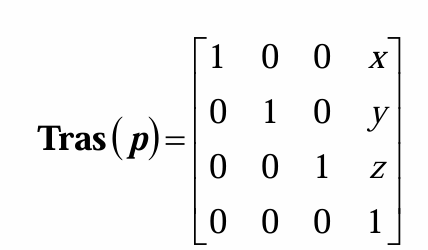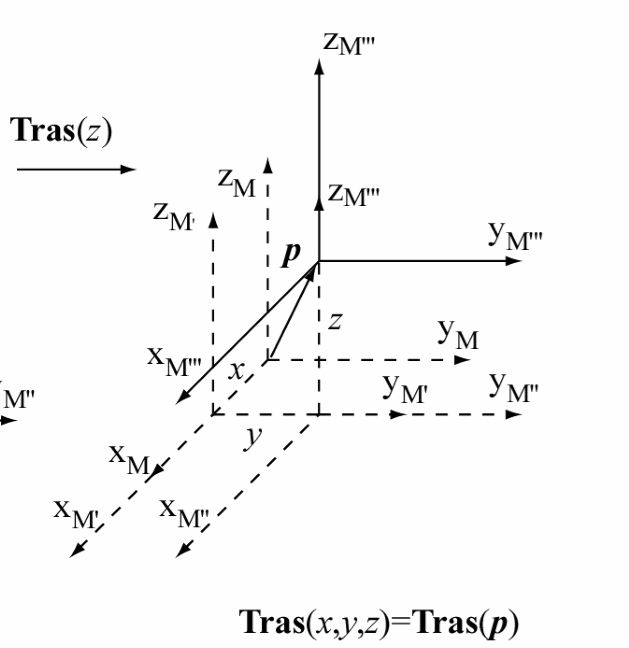

b. Rotación en el eje *X*

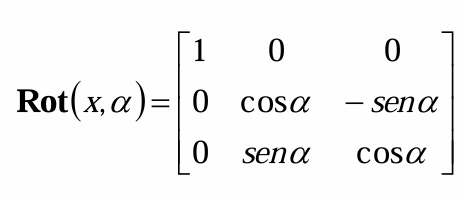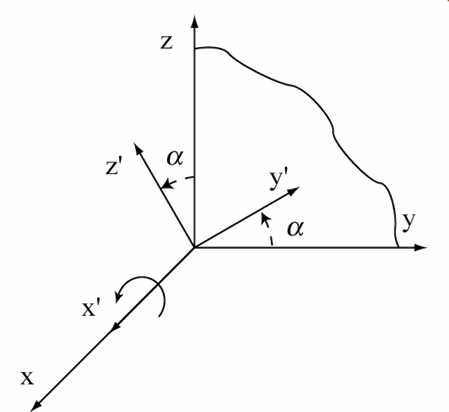

c. Rotación en el eje *Y* 

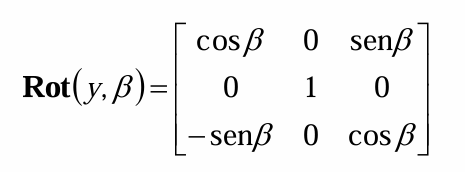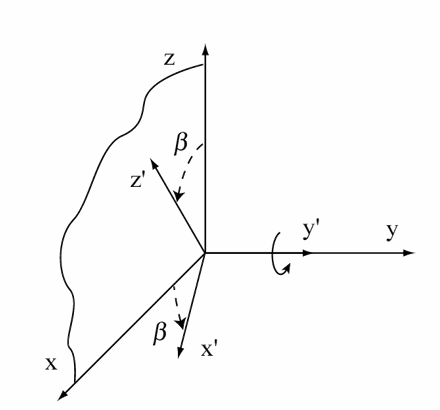

d. Rotación en el eje *Z* 

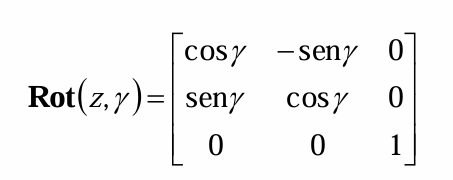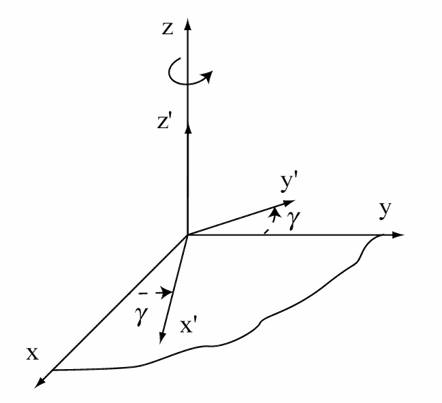

### Ejercicio 4 (obligatorio)

En la siguiente figura se observa el vector $a$ respecto del sistema {$M$}.  El punto $M$ respecto de {$O$} es ${}^Op_M$=(7,4).  

a. Halle, por el método que elija, el ángulo de rotación del sistema {$M$} respecto de {$O$}.

b. Exprese la matriz de transformación homogénea que describe la posición y orientación  del sistema {$M$} respecto de {$O$}.  

c. Use la transformación hallada para representar el vector *a* respecto del sistema {$O$}.  Verifique gráficamente el resultado.   

### Ejercicio 5

Escriba la matriz de transformación homogénea que representa la posición y  orientación del sistema {$M$} respecto de {$O$} para cada caso. Realice un gráfico donde se  aprecie la diferencia.  

a. El sistema {$M$} giró 45° respecto del eje $Y_M$, luego se trasladó un vector ${}^{M}\rho$ = (0 0 1)


$$T=\left\lbrack \begin{array}{cccc}
\cos \left(45\right) & 0 & \mathrm{sen}\left(45\right) & 0\\
0 & 1 & 0 & 0\\
-\mathrm{sen}\left(45\right) & 0 & \cos \left(45\right) & 0\\
1 & 1 & 1 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 1\\
1 & 1 & 1 & 1
\end{array}\right\rbrack$$


b. El sistema {$M$} se trasladó un vector ${}^{M}\rho$ = (0,0,1), luego giró 45° respecto del eje $Y_M$.


$$T=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 1\\
1 & 1 & 1 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{cccc}
\cos \left(45\right) & 0 & \mathrm{sen}\left(45\right) & 0\\
0 & 1 & 0 & 0\\
-\mathrm{sen}\left(45\right) & 0 & \cos \left(45\right) & 0\\
1 & 1 & 1 & 1
\end{array}\right\rbrack$$


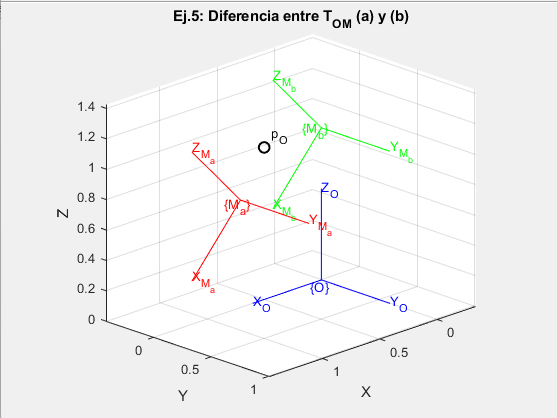

### Ejercicio 6

Exprese el vector ${}^0p$=(0.5   0   1) respecto del sistema {$M$} de cada caso del  ejercicio anterior.


$${}^{M}\rho = T^{-1} \cdot {}^{O}\rho$$


Para el ejercicio a)


$$p=\left\lbrack \begin{array}{ccc}
-0\ldotp 353553 & 0 & 0\ldotp 060660
\end{array}\right\rbrack$$


Para el ejercicio b)


$$p=\left\lbrack \begin{array}{ccc}
0\ldotp 353553 & 0 & 0\ldotp 353553
\end{array}\right\rbrack$$


### Ejercicio 7

Analizar la siguiente transformación compuesta e indicar V o F. Considere que {$T$}  representa la posición y orientación de un sistema de referencia {$M$} respecto de otro sistema  de referencia {$O$}.


$$T=T\;{\mathrm{Rot}}_X \left(a\right)*\mathrm{Ttras}\left(0,2,0\right)*T\;{\mathrm{Rot}}_Y \left(\beta \;\right)$$


a. El sistema {$M$} sufrió una rotación $\alpha$ respecto de $X_O$, luego una traslación de 2  unidades sobre el eje $Y_O$, y finalmente una rotación$\beta$ respecto de este mismo eje.  

a) **Falso.** Describe el orden al revés: en $T$ la rotación β sobre $Y_O$ ocurre primero y la α  sobre $X_O$ último.

b. El sistema {$M$} sufrió una rotación $\alpha$ respecto de $X_M$, luego una traslación de 2  unidades sobre el eje $Y_M$, y finalmente una rotación $\beta$ respecto de este mismo eje.

b) **Falso.** Las operaciones de $T$ están respecto a {$O$}, no a {$M$}. (Para ejes móviles se postmultiplica.)

c. Un vector $p$ expresado en {$O$} puede expresarse en {$M$} realizando el producto: ${}^{M}\rho = T \cdot \rho$

**Falso.** Para pasar un vector ($p$) de {$O$} a {$M$} se usa ${}^{M}\rho = T ^{-1}\rho$ , no la respuesta de la consigna.

d. Un vector $p$ expresado en {$M$} puede expresarse en {$O$} realizando el producto: ${}^{O}\rho = T \cdot \rho$

**Verdadero.**

syms a b real
Rx = [1 0 0 0; 0 cos(a) -sin(a) 0; 0 sin(a) cos(a) 0; 0 0 0 1];
Ty = [eye(3) [0;2;0]; 0 0 0 1];
Ry = [cos(b) 0 sin(b) 0; 0 1 0 0; -sin(b) 0 cos(b) 0; 0 0 0 1];

T = Rx * Ty * Ry;    % ^O T_M

% chequeo de mapeos
syms px py pz real
pM = [px; py; pz; 1];
pO = T*pM;           % coord. de p en {O}
pM_back = T\pO; % debe volver a pM
simplify(pM_back - pM)  % -> vector nulo

### Ejercicio 8

En función de las siguientes matrices escritas en forma simbólica halle la expresión  correcta para cada caso:

${}^OT_M$: matriz de trasformación homogénea del sistema {$M$} respecto de {$O$}.

${}^MT_A$: matriz de trasformación homogénea del sistema {$A$} respecto de {$M$}.

${}^AT_B$: matriz de trasformación homogénea del sistema {$B$} respecto de {$A$}.

${}^OT_F$: matriz de trasformación homogénea del sistema {$F$} respecto de {$O$}.

${}^FT_D$: matriz de trasformación homogénea del sistema {$D$} respecto de {$F$}.  

1. {$B$} respecto de {$O$}:

                
$${}^{B}a= ({}^{A}T_B)^{-1} \ ({}^{M}T_A)^{-1} \ ({}^{O}T_M)^{-1} \  {}^{O}a$$


2. {$F$} respecto de {$B$}:

                
$${}^{F}a= ({}^{O}T_F)^{-1} \ {}^{O}T_M \ {}^{M}T_A \ {}^{A}T_B \  {}^{B}a$$


3. {$B$} respecto de {$D$}:

                
$${}^{B}a= ({}^{A}T_B)^{-1} \  ({}^{M}T_A)^{-1} \  ({}^{O}T_M)^{-1} \ {}^{O}T_F \ {}^{F}T_D \  {}^{D}a$$
